# Horizon Chart

## Data Intialization and Preprocessing

First, we need to read the data and do some inital preprocessing to ensure that y is a 2d matrix and that x is either a 2d matrix with same dimensions as y or that x is 1d matrix with same number of rows as y. Labels is the individual title for each slice in the tiled layout. 

#### Note: All data is random and is for representation purposes only. The data is not indicative of real stock market data. Further, each column indicates the price of each stock for the years 2000 - 2021. 

n_stocks = 5;
[y_data, x_data, labels] = GenerateRandomData(5);

Let us create a basic horizon chart

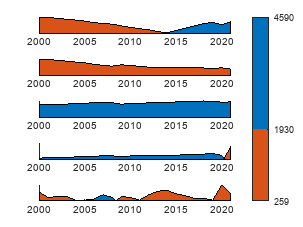

basicHorizonChart = horizonChart(x_data, y_data);

Let us add some labels to our chart. Here, each slice of the chart denotes the gdp of a country. So, we pass in country names as labels. 

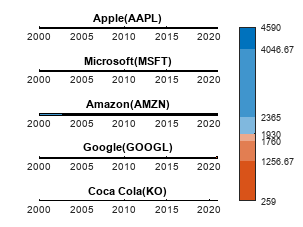

basicHorizonChart = horizonChart(x_data, y_data, 6, 'Labels', labels);

## Color Scheme

The horizon chart's color scheme is split into two zones: above the baseline and below the baseline. The user is required to specify a color for each zone. The segments in the chart are colored with a darker shade of the specified color based on their distance from the baseline. To set colors for the segments above and below the baseline, we can..

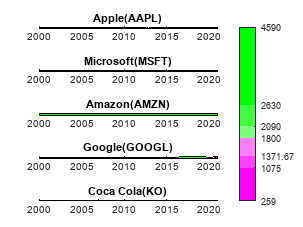

coloredHorizonChart = horizonChart(x_data, y_data, 6, 'Labels', labels, 'ColorAboveBaseline' , 'g' , 'ColorBelowBaseline' , 'm', 'Baseline', 1800);

## Baseline

We can also set the baseline according to our preferences. In this case, depending on distribution of data we accordingly rearrange the number of bands above the baseline/ below the baseline. 

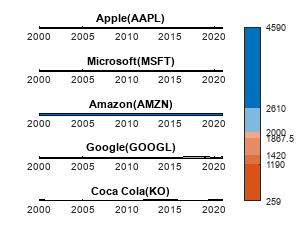

baselineHorizonChart = horizonChart(x_data, y_data , 6, 'Labels', labels, 'Baseline', 2000);

## Labelling the chart

To decorate the chart, we can also add the X-Label, Y-Label and chart title. 

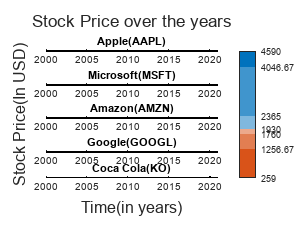

basicHorizonChart = horizonChart(x_data, y_data, 6, 'Labels', labels, 'XLabel', 'Time(in years)', 'YLabel', 'Stock Price(In USD)', 'Title', 'Stock Price over the years');